# LOADING THE VARIABLES FOR THE TEST

clear
close all
clc

load('myFunctions.mat')
% quite large, but the backtracking strategy is helping us to reducing as much as we need for obtaining a decrement of the loss function
alpha0 = 5;  
c1 = 1e-4;
rho = 0.5;
btmax = 50;

x0 = x0_rose_good;
f = f_rose;

gradf = gradf_rose;
kmax = 3000;
tolgrad = 1.0E-8;

## RUN THE STEEPEST DESCENT

disp('**** STEEPEST DESCENT: START *****')

**** STEEPEST DESCENT: START *****



[xk, fk, gradfk_norm, k, xseq, btseq] = ...
    steepest_desc_bt(x0, f, gradf, alpha0, kmax, ...
    tolgrad, c1, rho, btmax)

xk =     1.0060
    1.0121


fk = 3.6281e-05

gradfk_norm = 0.0131

k = 3000

xseq =     1.0589    1.1298    1.1011    1.1144    1.1085    1.1111    1.1098    1.1103    1.1100    1.1102    1.1099    1.1100    1.1098    1.1099    1.1097    1.1097    1.1094    1.1096    1.1093    1.1094    1.1091    1.1093    1.1090    1.1091    1.1089    1.1089    1.1086    1.1088    1.1085    1.1087    1.1084    1.1085    1.1082    1.1084    1.1079    1.1082    1.1080    1.1081    1.1077    1.1079    1.1076    1.1078    1.1075    1.1076    1.1074    1.1074    1.1072    1.1073    1.1070    1.1071
    1.2586    1.2251    1.2376    1.2315    1.2340    1.2327    1.2331    1.2328    1.2328    1.2325    1.2325    1.2322    1.2322    1.2319    1.2319    1.2314    1.2314    1.2311    1.2311    1.2308    1.2308    1.2305    1.2305    1.2302    1.2302    1.2299    1.2298    1.2296    1.2295    1.2293    1.2292    1.2290    1.2289    1.2287    1.2285    1.2282    1.2282    1.2277    1.2277    1.2274    1.2274    1.2271    1.2271    1.2268    1.2268    1.2265    1.2265    1.2260    1.2260  

btseq =     12    12    12    12    12    12    12    12    12    11    12    11    12    11    12    10    12    11    12    11    12    11    12    11    12    11    11    12    11    12    11    12    11    12    10    12    12    10    12    11    12    11    12    11    12    11    12    10    12    12


disp('**** STEEPEST DESCENT: FINISHED *****')

**** STEEPEST DESCENT: FINISHED *****


disp('**** STEEPEST DESCENT: RESULTS *****')

**** STEEPEST DESCENT: RESULTS *****


disp('************************************')

************************************


disp(['xk: ', mat2str(xk), ' (actual minimum: [0; 0]);'])

xk: [1.00602334930379;1.01208045977649] (actual minimum: [0; 0]);


disp(['f(xk): ', num2str(fk), ' (actual min. value: 0);'])

f(xk): 3.6281e-05 (actual min. value: 0);


disp(['N. of Iterations: ', num2str(k),'/',num2str(kmax), ';'])

N. of Iterations: 3000/3000;


disp('************************************')

************************************


## PLOTS

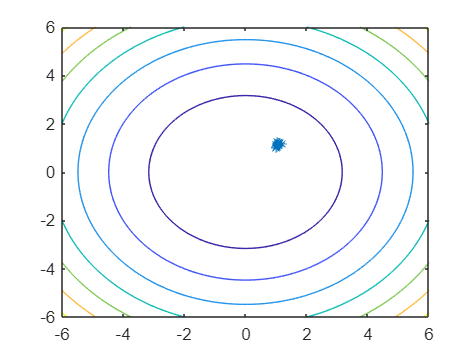

% Creation of the meshgrid for the contour-plot
[X, Y] = meshgrid(linspace(-6, 6, 500), linspace(-6, 6, 500));
% Computation of the values of f for each point of the mesh
Z = X.^2 + Y.^2;

% Plots

% Simple Plot
fig1 = figure();
% Contour plot with curve levels for each point in xseq
[C1, ~] = contour(X, Y, Z);
hold on
% plot of the points in xseq
plot([x0(1) xseq(1, :)], [x0(2) xseq(2, :)], '--*')
hold off

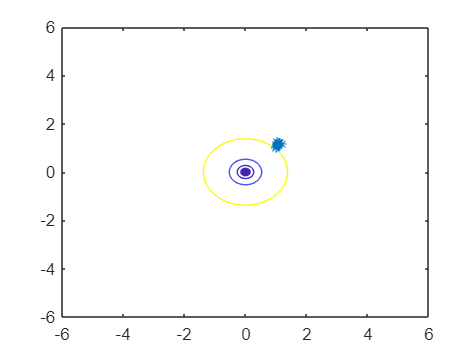


% More interesting Plot
fig2 = figure();
% Contour plot with curve levels for each point in xseq
% ATTENTION: actually, the mesh [X, Y] is to coarse for plotting the last
% level curves corresponding to the last point in xseq (check it zooming
% the image).
[C2, ~] = contour(X, Y, Z, f(xseq));
hold on
% plot of the points in xseq
plot([x0(1) xseq(1, :)], [x0(2) xseq(2, :)], '--*')
hold off

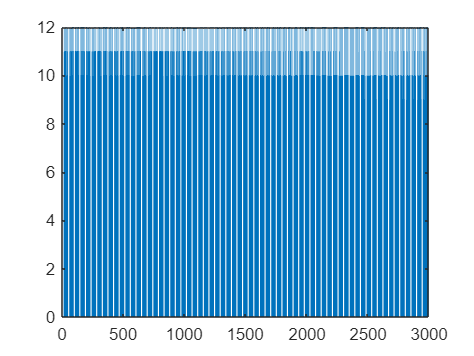


% Barplot of btseq
% In each of iteration of the steepest descent the backtracking strategy
% have been executed and the number of iterations of backtracking strategy
% is equal to 8 for each step of the steepest descent --> the steplength
% factor alpha_k=rho^8 * alpha_0
fig3 = figure();
bar(btseq)

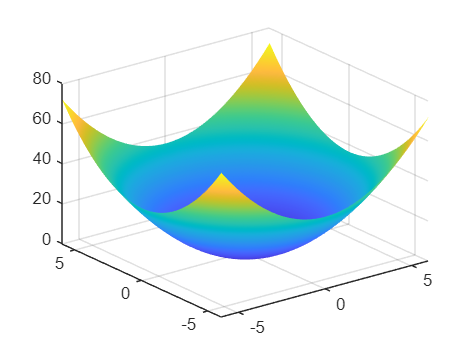


% Much more interesting plot
fig4 = figure();
surf(X, Y, Z,'EdgeColor','none')
hold on
plot3([x0(1) xseq(1, :)], [x0(2) xseq(2, :)], [f(x0), f(xseq)], 'r--*')
hold off